1번 문제

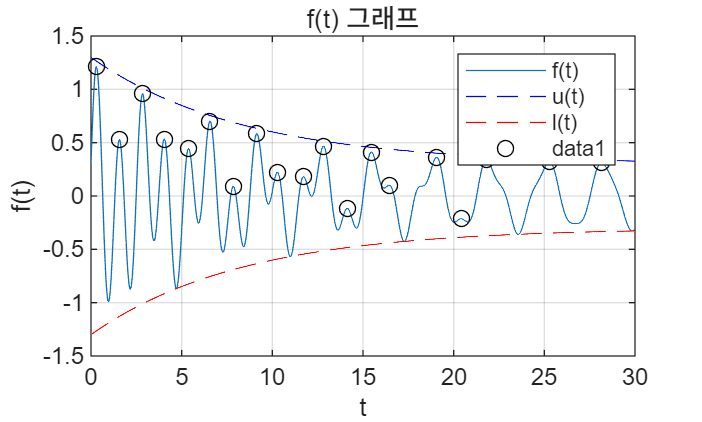

clear;
clc;

t=0:0.01:30;

f=exp(-0.12*t).*sin(5*t)+0.3*cos(2*t);

%a번 문제
figure;
plot(t,f);
xlabel('t');
ylabel('f(t)');
title('f(t) 그래프');
grid on;

%b번 문제
u=exp(-0.12*t)+0.3;
l=-exp(-0.12*t)-0.3;
hold on;

plot(t,u,'b--');
plot(t,l,'r--');
legend('f(t)','u(t)','l(t)');

%c번 문제
idx=find((f(2:end-1)>f(1:end-2))&(f(2:end-1)>f(3:end)))+1;

%d번 문제
plot(t(idx),f(idx),'ok');


%e번 문제
result=[t(idx)',f(idx)'];
disp(result);

    0.3000    1.2098
    1.5700    0.5283
    2.8400    0.9569
    4.0400    0.5337
    5.3800    0.4442
    6.5600    0.7024
    7.8500    0.0898
    9.1400    0.5830
   10.2800    0.2222
   11.7200    0.1808
   12.8200    0.4672
   14.1300   -0.1166
   15.4600    0.4118
   16.4400    0.1009
   19.0600    0.3620
   20.4100   -0.2137
   21.8000    0.3380
   25.2800    0.3194
   28.1500    0.3106



2번 문제

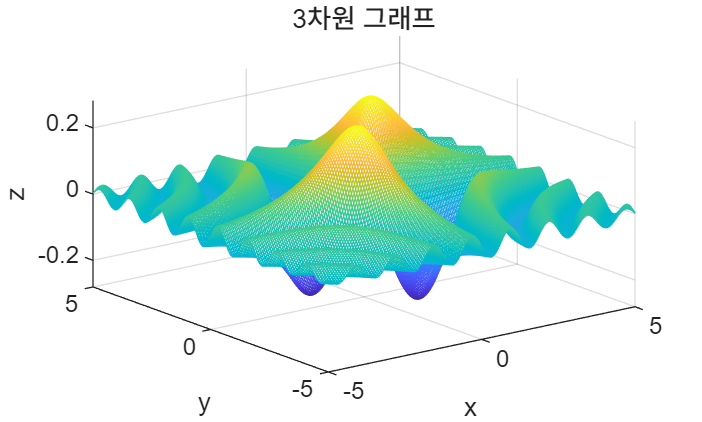

clear;
clc;

x=-5:0.05:5;
y=-5:0.05:5;

[X,Y]=meshgrid(x,y);

%a번 문제
Z=sin(X.*Y)./(1+X.^2+Y.^2);

%b번 문제
figure;

mesh(X,Y,Z);
xlabel('x');
ylabel('y');
zlabel('z');
title('3차원 그래프');
grid on;

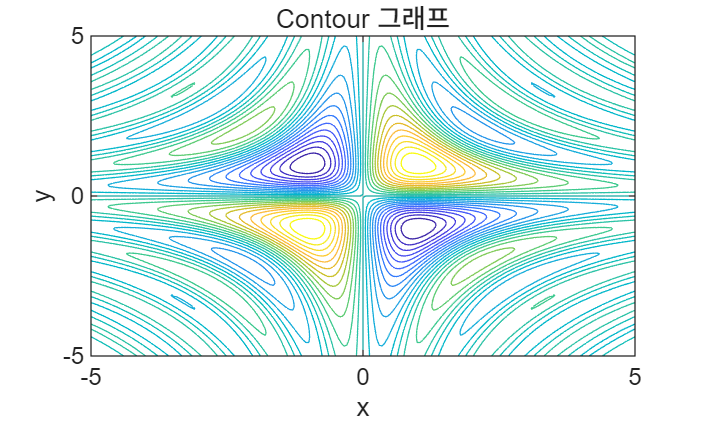


%c번 문제
figure;

contour(X,Y,Z,25);
xlabel('x');
ylabel('y');
title('Contour 그래프');
grid on;


%d번 문제
Zmax=max(abs(Z(:)));
disp(Zmax);

    0.2805




%e번 문제
idx=find(abs(Z)==Zmax);

Xmax=X(idx);
Ymax=Y(idx);

disp([Xmax,Ymax]);

    -1    -1
    -1     1
     1    -1
     1     1



3번 문제

clear;
clc;

A=[7 2 1;2 6 -2;1 -2 5];

%a번 문제
[V,D]=eig(A);

disp(V);

    0.4219    0.5548    0.7171
   -0.6189   -0.4018    0.6749
   -0.6626    0.7285   -0.1738



disp(D);

    2.4953         0         0
         0    6.8646         0
         0         0    8.6400




%b번 문제
eigenvalues=diag(D);
disp(eigenvalues);

    2.4953
    6.8646
    8.6400




%c번 문제
[eigenvalues_max,idx]=max(eigenvalues);
disp(eigenvalues_max);

    8.6400



disp(idx);

     3




%d번 문제
v=V(:,idx);

%e번 문제
u=v/norm(v);
disp(u);

    0.7171
    0.6749
   -0.1738




%f번 문제
result=A*v-eigenvalues_max*v;
disp(result);

   1.0e-14 *

   -0.0888
    0.3553
    0.0444



4번 문제

clear;
clc;

X=[2 5 1;4 8 3;6 11 7;9 15 10;13 20 14];

%a번 문제
m=mean(X);
disp(m);

    6.8000   11.8000    7.0000




%b번 문제
Xc=X-m;
disp(Xc);

   -4.8000   -6.8000   -6.0000
   -2.8000   -3.8000   -4.0000
   -0.8000   -0.8000         0
    2.2000    3.2000    3.0000
    6.2000    8.2000    7.0000




%c번 문제
S=Xc'*Xc;
disp(S);

   74.8000  101.8000   90.0000
  101.8000  138.8000  123.0000
   90.0000  123.0000  110.0000




%d번 문제
[V,D]=eig(S);
disp(D);

    0.0473         0         0
         0    0.8388         0
         0         0  322.7139




%e번 문제
eigenvalues=diag(D);
[eigenvalues_max,idx]=max(eigenvalues);
disp(eigenvalues_max);

  322.7139




%f번 문제
v=V(:,idx);
disp(v);

    0.4806
    0.6556
    0.5824



5번 문제

clear;
clc;

%a번 문제
A=[5 2 -1;-2 6 3; 1 -1 7];
b=[8;5;12];

%b번 문제
x1=inv(A)*b;
disp(x1);

    1.6692
    0.6084
    1.5627




%c번 문제
x2=A\b;
disp(x2);

    1.6692
    0.6084
    1.5627




%d번 문제
difference=x1-x2;
disp(difference);

   1.0e-15 *

    0.2220
    0.2220
         0




%e번 문제
disp(det(A));

   263



%det(A)의 값이 0이 아니므로 해가 유일하게 존재한다.

6번 문제

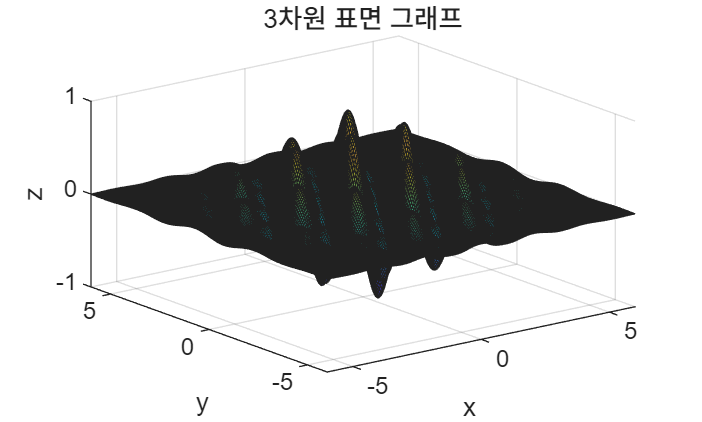

clear;
clc;

x=-6:0.05:6;
y=-6:0.05:6;

%a번 문제
[X,Y]=meshgrid(x,y);
Z=exp(-0.08*(X.^2+Y.^2)).*cos(3*X).*sin(2*Y);

%b번 문제
figure;
surf(X,Y,Z);
xlabel('x');
ylabel('y');
zlabel('z');
title('3차원 표면 그래프');
grid on;

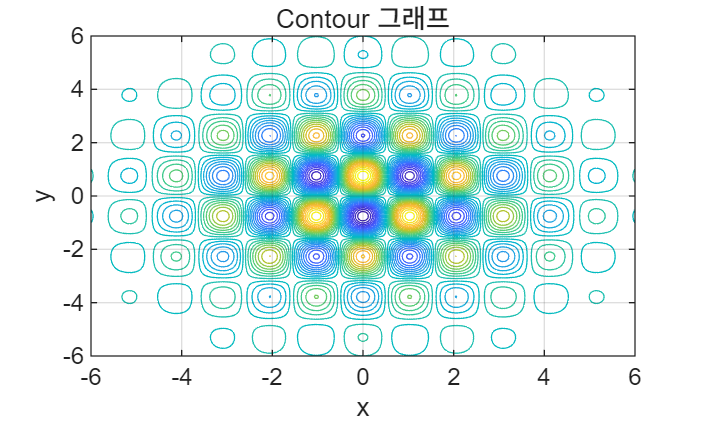


%c번 문제
figure;
contour(X,Y,Z,30);
xlabel('x');
ylabel('y');
title('Contour 그래프');
grid on;


%d번 문제
Zmax=max(Z(:));
Zmin=min(Z(:));

disp(Zmax);

    0.9536



disp(Zmin);

   -0.9536




%e번 문제
idx_max=find(Z==Zmax);
[row_max,col_max]=ind2sub(size(Z),idx_max);
x_max=X(row_max,col_max);
y_max=Y(row_max,col_max);

disp([x_max,y_max]);

         0    0.7500




idx_min=find(Z==Zmin);
[row_min,col_min]=ind2sub(size(Z),idx_min);
x_min=X(row_min,col_min);
y_min=Y(row_min,col_min);

disp([x_min,y_min]);

         0   -0.7500



7번 문제

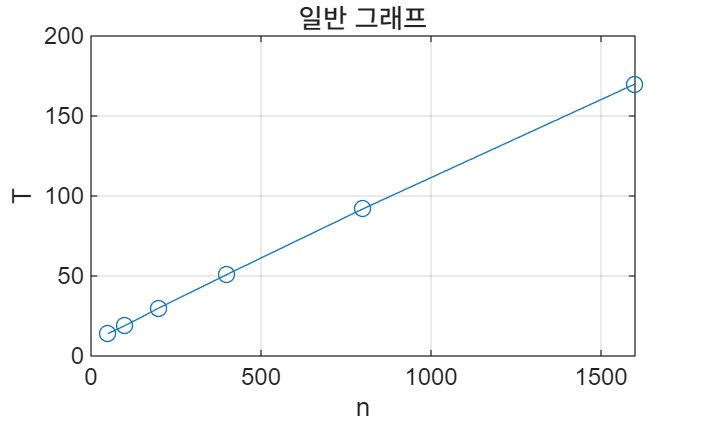

clear;
clc;

n=[50 100 200 400 800 1600];
T=[14 19 30 51 92 170];

%a번 문제
figure;
plot(n,T,'o-');
xlabel('n');
ylabel('T');
title('일반 그래프');
grid on;

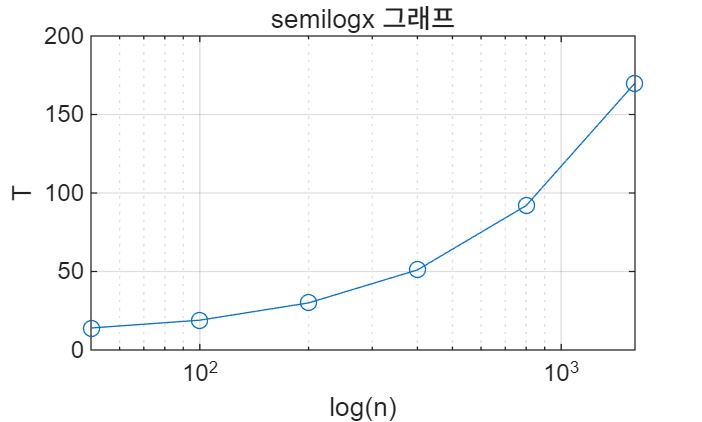


%b번 문제
figure;
semilogx(n,T,'o-');
xlabel('log(n)');
ylabel('T');
title('semilogx 그래프');
grid on;

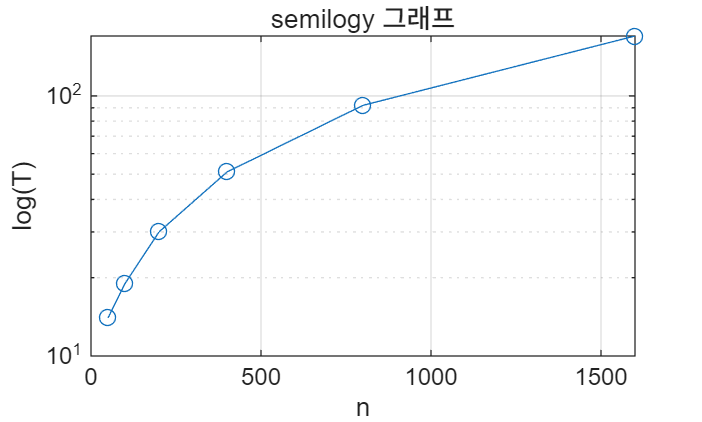


%c번 문제
figure;
semilogy(n,T,'o-');
xlabel('n');
ylabel('log(T)');
title('semilogy 그래프');
grid on;

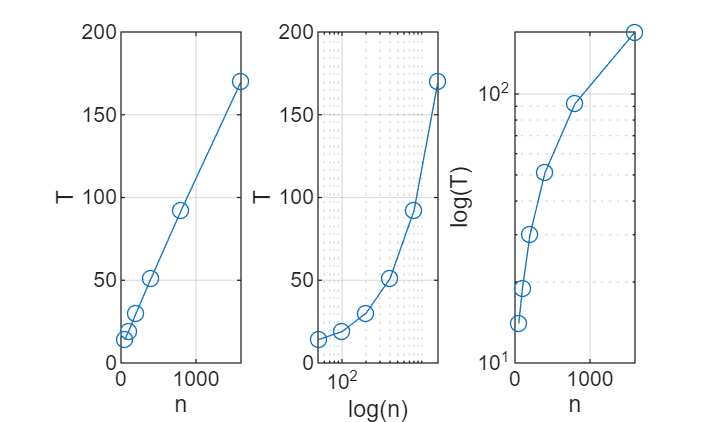


%d번 문제
figure;

subplot(1,3,1);
plot(n,T,'o-');
xlabel('n');
ylabel('T');
grid on;

subplot(1,3,2);
semilogx(n,T,'o-');
xlabel('log(n)');
ylabel('T');
grid on;

subplot(1,3,3);
semilogy(n,T,'o-');
xlabel('n');
ylabel('log(T)');
grid on;


%e번 문제
%가장 직선에 가깝게 보이는 그래프는 plot 일반 그래프다.

plot 일반 그래프

8번 문제

clear;
clc;

t=0:0.01:24;

%a번 문제
P=50+18*sin(pi*t/12)+6*cos(pi*t/4);
figure;

plot(t,P);
xlabel('t');
ylabel('P(t)');
title('하루 전력 사용량 그래프');
grid on;

%b번 문제
Pmax=max(P);
disp(Pmax);

   72.1731




%c번 문제
idx_max=find(P==Pmax);
t_max=t(idx_max);
disp(t_max);

    7.5000




%d번 문제
Pmin=min(P);
idx_min=find(P==Pmin);
t_min=t(idx_min);
disp(Pmin);

   27.8269



disp(t_min);

   19.5000



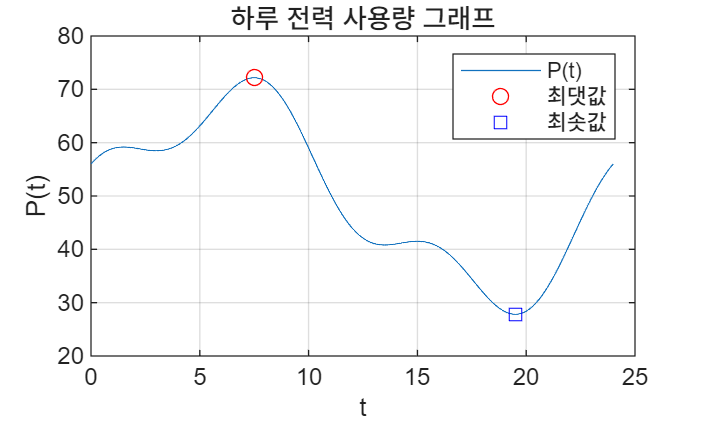


%e번 문제
hold on;
plot(t_max,Pmax,'ro');
plot(t_min,Pmin,'bs');
legend('P(t)','최댓값','최솟값');

9번 문제

clear;
clc;

X=[1 3 0;2 5 1;4 8 3; 7 12 5;11 17 9];

%a번 문제
x1=X(:,1);
x2=X(:,2);
x3=X(:,3);

%b번 문제
angle12=acos(dot(x1,x2)/(norm(x1)*norm(x2)))*(180/pi);
disp(angle12);

    7.1357




%c번 문제
angle13=acos(dot(x1,x3)/(norm(x1)*norm(x3)))*(180/pi);
disp(angle13);

    6.1221



angle23=acos(dot(x2,x3)/(norm(x2)*norm(x3)))*(180/pi);
disp(angle23);

   12.8186




%d번 문제
angle=[angle12,angle13,angle23];
disp(angle);

    7.1357    6.1221   12.8186




%e번 문제
[angle_min,idx]=min(angle);
disp(angle_min);

    6.1221




if idx==1
    disp('x1,x2');
elseif idx==2
    disp('x1,x3');
elseif idx==3
    disp('x2,x3');
end

x1,x3


10번 문제

clear;
clc;

%a번 문제
A=[9 -2 -1;-2 8 -3;-1 -3 10];
b=[15;7;11];

%b번 문제
I=A\b;
disp(I);

    2.3834
    2.2228
    2.0052




%c번 문제
d=det(A);
disp(d)

   579



if d~=0
    disp('가역행렬');
else
    disp('비가역행렬');
end

가역행렬



%d번 문제
I_abs=abs(I);
disp(I_abs);

    2.3834
    2.2228
    2.0052




%e번 문제
[I_max,idx]=max(I_abs);
disp(I_max);

    2.3834



disp(idx);

     1



11번 문제

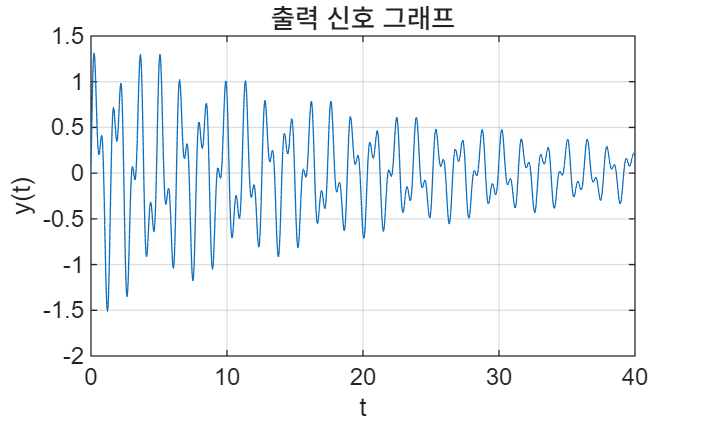

clear;
clc;

t=0:0.01:40;
%a번 문제
y=exp(-0.04*t).*(sin(4*t)+0.6*sin(9*t));
figure;
plot(t,y);
xlabel('t');
ylabel('y(t)');
title('출력 신호 그래프');
grid on;

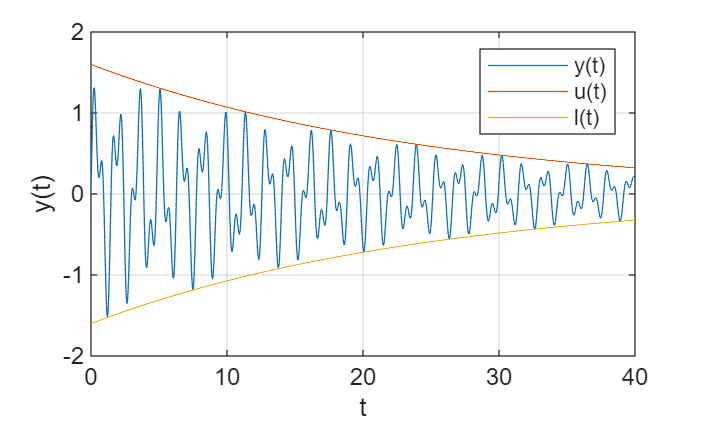


%b번 문제
u=1.6*exp(-0.04*t);
l=-1.6*exp(-0.04*t);

%c번 문제
figure;
plot(t,y);
hold on;

plot(t,u);
plot(t,l);
xlabel('t');
ylabel('y(t)');
legend('y(t)','u(t)','l(t)');

grid on;

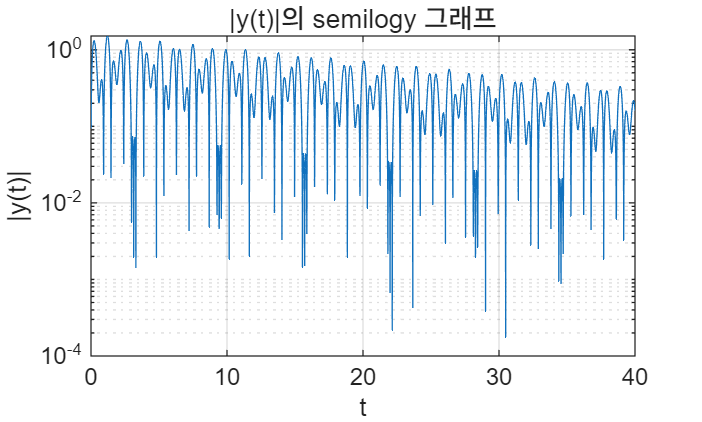


%d번 문제
figure;
semilogy(t,abs(y));
xlabel('t');
ylabel('|y(t)|');
title('|y(t)|의 semilogy 그래프');
grid on;


%e번 문제
u0=1.6*exp(-0.04*0);
u40=1.6*exp(-0.04*40);

disp(u0);

    1.6000



disp(u40);

    0.3230



12번 문제

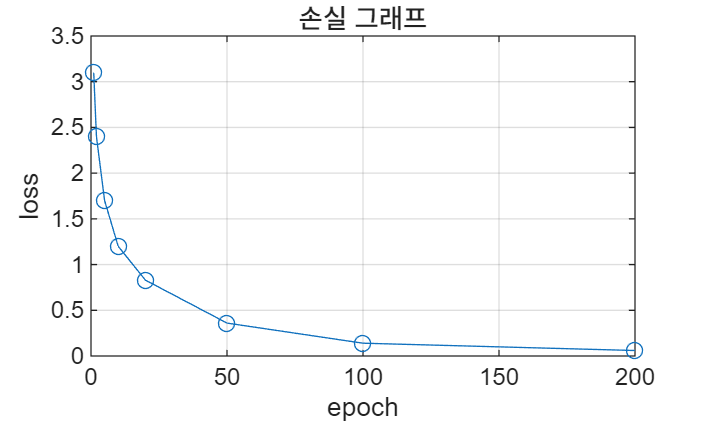

clear;
clc;

epoch=[1 2 5 10 20 50 100 200];
loss=[3.1 2.4 1.7 1.2 0.83 0.36 0.14 0.06];

%a번 문제
figure;
plot(epoch,loss,'o-');
xlabel('epoch');
ylabel('loss');
title('손실 그래프');
grid on;

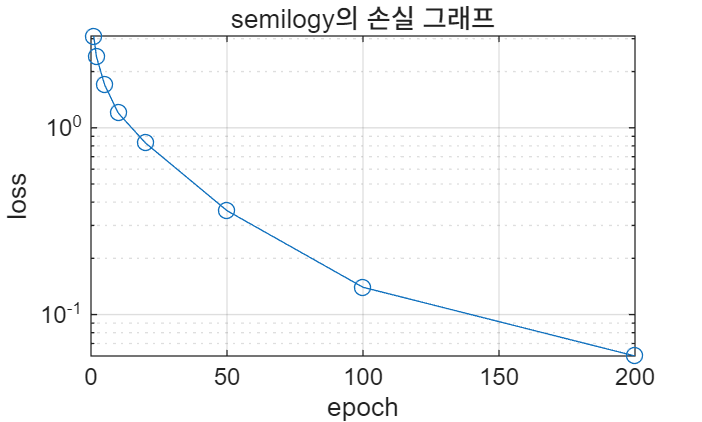


%b번 문제
figure;
semilogy(epoch,loss,'o-');
xlabel('epoch');
ylabel('loss');
title('semilogy의 손실 그래프');
grid on;


%c번 문제
r=loss(2:end)./loss(1:end-1);
disp(r);

    0.7742    0.7083    0.7059    0.6917    0.4337    0.3889    0.4286




%d번 문제
r_mean=mean(r);
disp(r_mean);

    0.5902




%e번 문제
%평균비율이 1보다 작으므로 전반적으로 감소한다.

전반적으로 감소한다.